% Define the file path
filePath = '/Users/jacoby/CHE260/lab 2 - part 2 a';

%read data from file
fid = fopen(filePath, 'r');
for i = 1:3
    fgetl(fid);
end
data = readtable(filePath, 'FileType', 'text', 'Delimiter', '\t', 'HeaderLines', 3);
fclose(fid);
data = table2array(data)

data =          0   23.9000   23.6000   23.5000   23.4000   39.7000    0.1000         0         0
    0.1000   23.9000   23.4000   23.3000   23.3000   40.0000    0.4000         0         0
    0.2000   24.0000   23.6000   23.4000   23.2000   39.5000    0.3000         0         0
    0.3000   24.0000   23.6000   23.4000   23.2000   39.4000   -0.2000         0         0
    0.4000   23.9000   23.5000   23.3000   23.2000   39.4000   -0.2000         0         0
    0.5000   23.9000   23.5000   23.4000   23.3000   39.4000    0.3000         0         0
    0.6000   23.9000   23.5000   23.4000   23.3000   39.5000   -0.3000         0         0
    0.7000   24.0000   23.6000   23.4000   23.4000   39.7000    0.1000         0         0
    0.8000   23.8000   23.6000   23.4000   23.2000   40.0000    0.1000         0         0
    0.9000   23.8000   23.6000   23.4000   23.2000   39.5000    0.1000         0         0



time = data(113:860, 1)

time =    11.2000
   11.3000
   11.4000
   11.5000
   11.6000
   11.7000
   11.8000
   11.9000
   12.0000
   12.1000


T1 = data(113:860, 2);
Wall_temp = data(:, 3);
Top_plate = data(:, 4);
Bottom_plate = data(:, 5);
P1 = data(:, 6);
P2 = data(:, 7);
mass_flowrate = data(:, 8)

mass_flowrate =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Heat_energy = data(113:860, 9);



% Linear fit for T1 with respect to time
p_T1 = polyfit(time, T1, 1); 
slope_T1 = p_T1(1);
intercept_T1 = p_T1(2);

% Calculate uncertainty in slope
n = length(time);
y_fit_T1 = polyval(p_T1, time);
SS_res_T1 = sum((T1 - y_fit_T1).^2);
slope_uncertainty_T1 = sqrt(SS_res_T1 / ((n - 2) * sum((time - mean(time)).^2)));

% Display the slope, intercept, and uncertainty
disp('Best-fit slope for T1 with respect to time:');

Best-fit slope for T1 with respect to time:


disp(slope_T1);

    0.2275



disp('Intercept of the best-fit line for T1:');

Intercept of the best-fit line for T1:


disp(intercept_T1);

   22.5392



disp('Uncertainty in the slope for T1:');

Uncertainty in the slope for T1:


disp(slope_uncertainty_T1);

    0.0017




% Plot T1 vs. time with the best-fit line
figure;
plot(time, T1, 'b-', 'DisplayName', 'T1 Data');
hold on;
plot(time, y_fit_T1, 'r--', 'DisplayName', 'Best Fit Line');
xlabel('Time (s)');
ylabel('T1');
title('Best Fit Line for T1 vs. Time');
legend('show');
hold off;



% Linear fit for Heat_energy with respect to time
p_Heat = polyfit(time, Heat_energy, 1); 
slope_Heat = p_Heat(1);
intercept_Heat = p_Heat(2);

% Calculate uncertainty in slope for Heat_energy
y_fit_Heat = polyval(p_Heat, time);
SS_res_Heat = sum((Heat_energy - y_fit_Heat).^2);
slope_uncertainty_Heat = sqrt(SS_res_Heat / ((n - 2) * sum((time - mean(time)).^2)));

% Display the slope, intercept, and uncertainty for Heat_energy
disp('Best-fit slope for Heat_energy with respect to time:');

Best-fit slope for Heat_energy with respect to time:


disp(slope_Heat);

    0.6982



disp('Intercept of the best-fit line for Heat_energy:');

Intercept of the best-fit line for Heat_energy:


disp(intercept_Heat);

    3.8797



disp('Uncertainty in the slope for Heat_energy:');

Uncertainty in the slope for Heat_energy:


disp(slope_uncertainty_Heat);

    0.0074



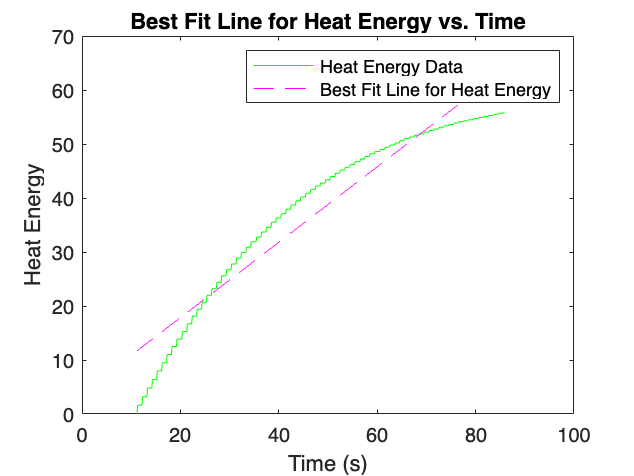



% Plot Heat_energy vs. time with the best-fit line
figure;
plot(time, Heat_energy, 'g-', 'DisplayName', 'Heat Energy Data');
hold on;
plot(time, y_fit_Heat, 'm--', 'DisplayName', 'Best Fit Line for Heat Energy');
xlabel('Time (s)');
ylabel('Heat Energy');
title('Best Fit Line for Heat Energy vs. Time');
legend('show');
hold off;


% Define mass and uncertainties
m = 34.7808e-3; % Example mass in kg
delta_m = 0; % Uncertainty in mass

% Calculate the rate of change of Heat_energy (dQ/dt) and T1 (dT/dt) using polyfit slopes
dQ_dt = slope_Heat;           % Slope from Heat_energy vs. time fit
dT_dt = slope_T1;             % Slope from T1 vs. time fit
delta_dQ_dt = slope_uncertainty_Heat;  % Uncertainty in dQ/dt
delta_dT_dt = slope_uncertainty_T1;    % Uncertainty in dT/dt

% Calculate Cv
cv = (1 / m) * (dQ_dt / dT_dt);

% Calculate uncertainty in Cv
delta_cv = sqrt((dQ_dt / (m^2 * dT_dt) * delta_m)^2 + ...
                ((1 / (m * dT_dt)) * delta_dQ_dt)^2 + ...
                ((dQ_dt / (m * dT_dt^2)) * delta_dT_dt)^2);

% Display Cv and its uncertainty
disp('Specific heat capacity, Cv:');

Specific heat capacity, Cv:


disp(cv);

   88.2256



disp('Uncertainty in Cv:');

Uncertainty in Cv:


disp(delta_cv);

    1.1376

